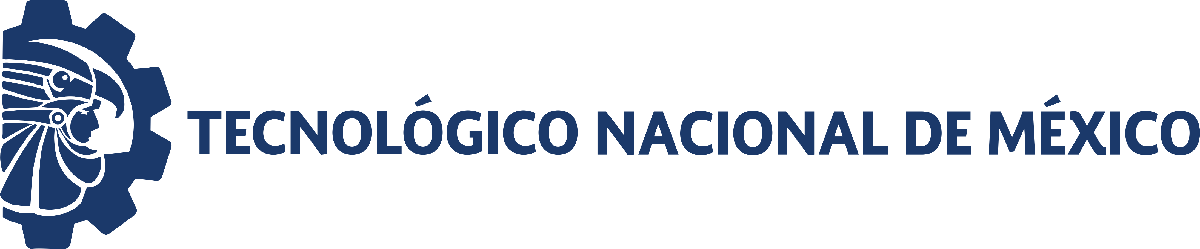                                 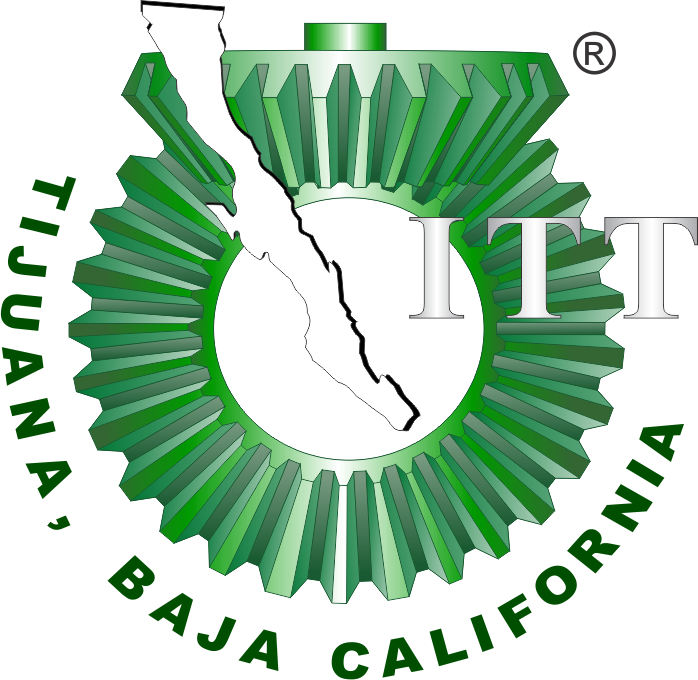

# Proyecto: Paciente con Covid-19

**Departamento de Ingeniería Eléctrica y Electrónica, Ingeniería Biomédica**

**Tecnológico Nacional de México [TecNM - Tijuana], Blvd. Alberto Limón Padilla s/n, C.P. 22454, Tijuana, B.C., México**

## Información general

Nombre del alumno: **Alexander Torres Avila**

Número de control: **21212848**

Correo institucional: **L21212848@tectijuana.edu.mx**

Asignatura: **Modelado de Sistemas Fisiológicos**

Docente: **Dr. Paul Antonio Valle Trujillo; paul.valle@tectijuana.edu.mx**

## Datos de la simulación

clc; clear; close all; warning ('off','all')
tend = '30';
file = 'Sistema_Final';
open_system(file);
parameters.StopTime = tend;
parameters.Solver = 'ode45';
parameters.MaxStep = '1E-3';

## Respiración normal

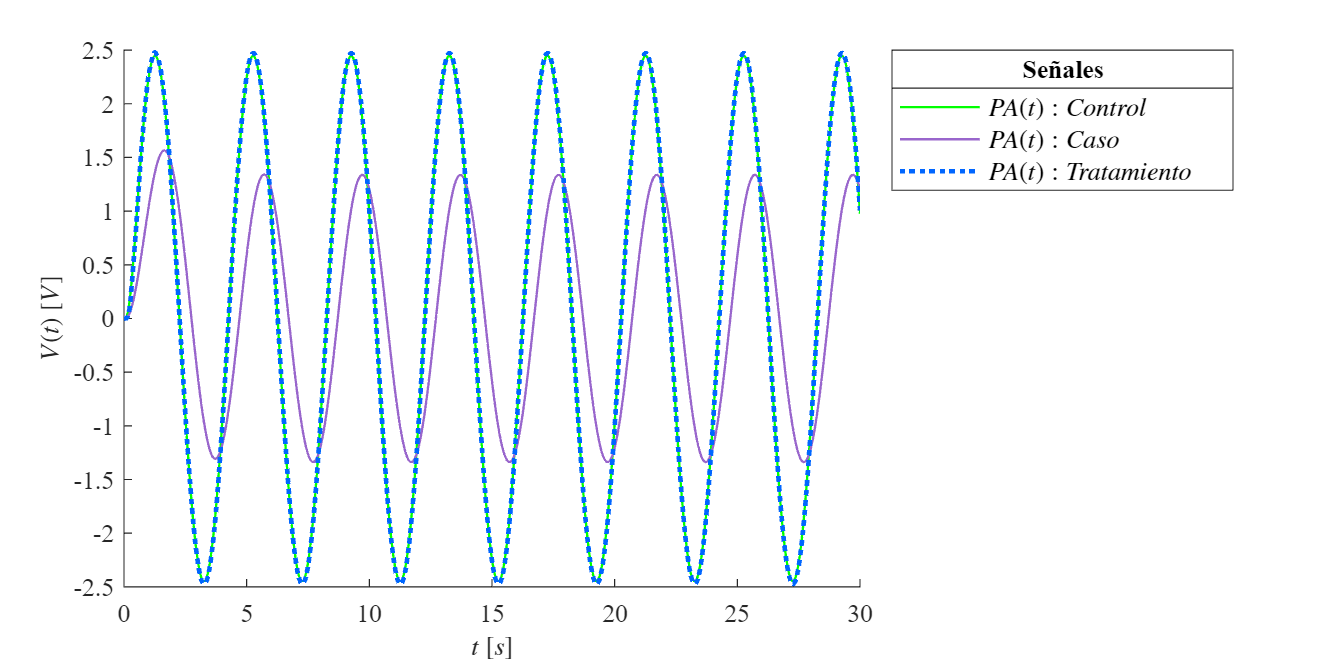

Signal = 'Paciente Sano';
set_param('Sistema_Final/Ve(t)','Amplitude','2.5');
set_param('Sistema_Final/Ve(t)','Frequency','pi/2');
N = sim(file,parameters);
plotsignals(N.t,N.PAx,N.PAy,N.PAz,Signal)

## Respiración anormal [COVID-19]

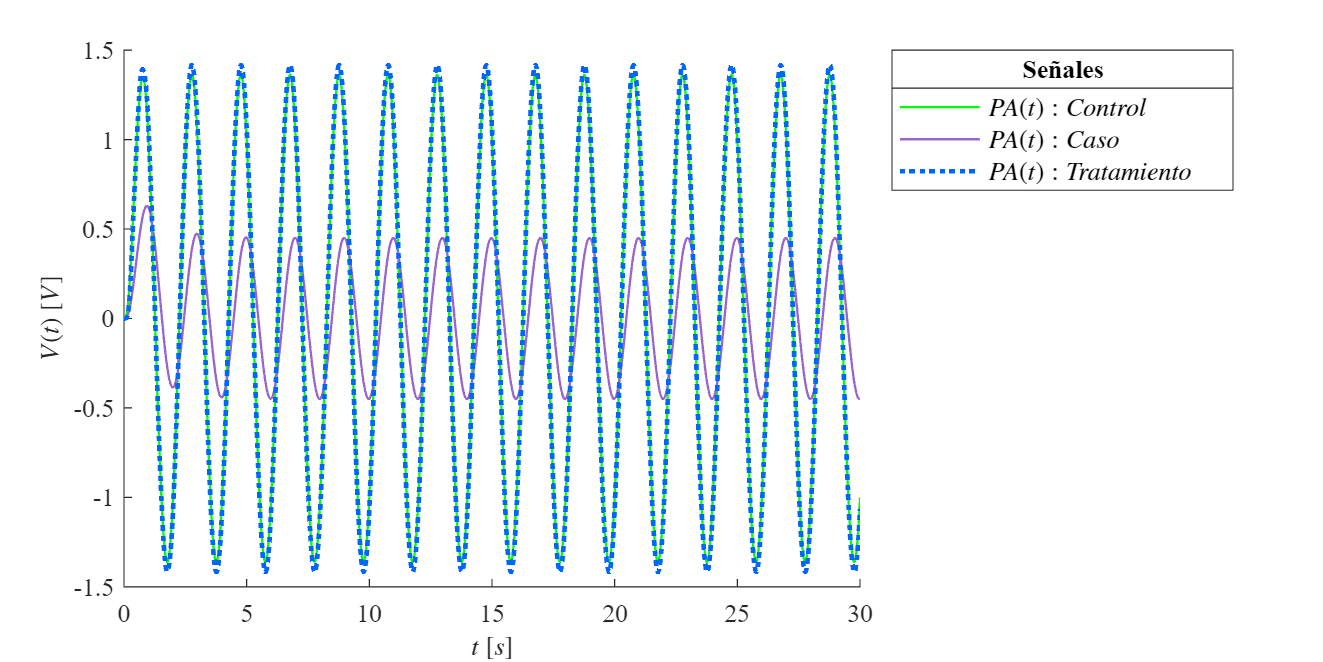

Signal = 'COVID-19';
set_param('Sistema_Final/Ve(t)','Amplitude','1.5');
set_param('Sistema_Final/Ve(t)','Frequency','pi');
T = sim(file,parameters);
plotsignals(T.t,T.PAx,T.PAy,T.PAz,Signal)

## Funciones

function plotsignals(t,PAx,PAy,PAz,Signal)
    set(figure(),'Color','W')
    set(gcf,'Units','Centimeters','Position',[1,5,20,10])
    set(gca,'FontName','TimesNewRoman','FontSize',11)
    hold on; grid off

    plot(t,PAx,'LineWidth',1,'Color',[0,1,0])
    plot(t,PAy,'LineWidth',1,'Color',[0.6,0.4,0.8])
    plot(t,PAz,':','LineWidth',2,'Color',[0,0.4,1])

    L = legend('$PA(t):Control$','$PA(t):Caso$','$PA(t):Tratamiento$');
    set(L,'Interpreter','Latex','FontSize',11,'Location','Bestoutside','Box','on')
    title(L,'Señales')

    xlabel('$t$ $[s]$','Interpreter','Latex','FontSize',11)
    ylabel('$V(t)$ $[V]$','Interpreter','Latex','FontSize',11)

    if Signal == "Paciente Sano"
        xlim([0,30]); xticks(0:5:30)
        ylim([-2.5,2.5]); yticks(-2.5:0.5:2.5)
    elseif Signal == "COVID-19"
        xlim([0,30]); xticks(0:5:30)
        ylim([-1.5,1.5]); yticks(-1.5:0.5:1.5)
    end
    exportgraphics(gcf,[Signal,'.pdf'],'ContentType','vector');
    exportgraphics(gcf,[Signal,'.png'],'Resolution',600);
end